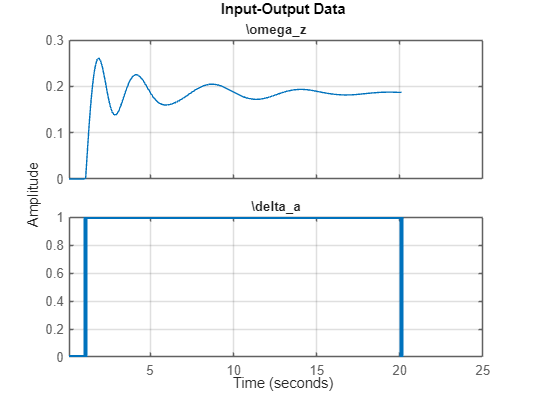

clear all; close all; clc

load simdata/step_20s_simdata.mat
% gives times, delta_a and omega_z arrays
Ts = times(2) - times(1);

% use iddata to collect and plot input/output data
data = iddata(omega_z, delta_a, Ts);
data.InputName  = '\delta_a';
data.InputUnit = '[fraction]';
data.OutputName = '\omega_z';
data.OutputUnit = 'rad/s';
data.TimeUnit = 'seconds';
plot(data);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

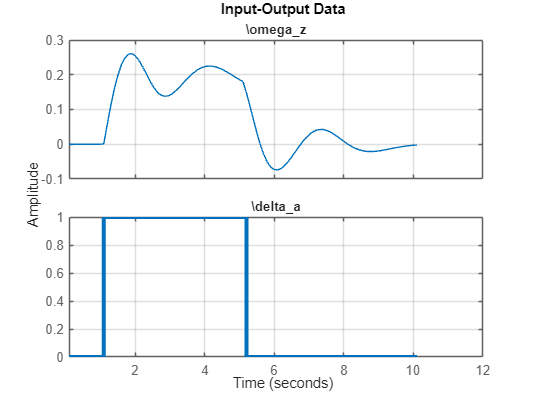

% collect and plot validation data
clear delta_a omega_z times
load simdata/shortstep_simdata.mat
% delta_a, omega_z, and times gets overwritten
Ts = times(2) - times(1);

validation_data = iddata(omega_z, delta_a, Ts);
validation_data.InputName  = '\delta_a';
validation_data.InputUnit = '[fraction]';
validation_data.OutputName = '\omega_z';
validation_data.OutputUnit = 'rad/s';
validation_data.TimeUnit = 'seconds';
plot(validation_data);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

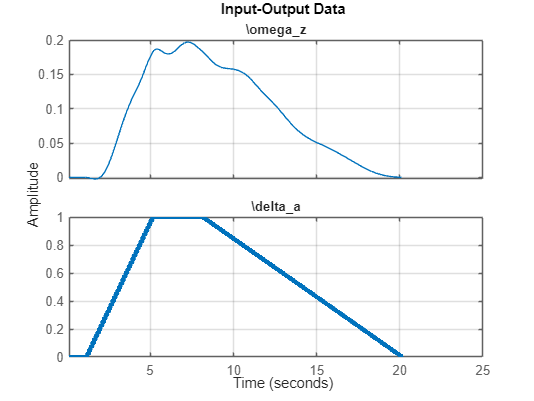



% collect and plot another set of validation data
clear delta_a omega_z times
load simdata/ramp_simdata.mat
% delta_a, omega_z, and times gets overwritten
Ts = times(2) - times(1);

validation_data2 = iddata(omega_z, delta_a, Ts);
validation_data2.InputName  = '\delta_a';
validation_data2.InputUnit = '[fraction]';
validation_data2.OutputName = '\omega_z';
validation_data2.OutputUnit = 'rad/s';
validation_data2.TimeUnit = 'seconds';
plot(validation_data2);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on


% fit first-order TF
sysTF = tfest(data, 2,1) % TF: 2 poles, 1 zero

sysTF =
  From input "\delta_a" to output "\omega_z":
    0.4339 s + 1.933
  --------------------
  s^2 + 1.87 s + 10.46
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 75.15%                   
FPE: 0.0001464, MSE: 0.0001379                   
 
Model Properties


**Validate Model**

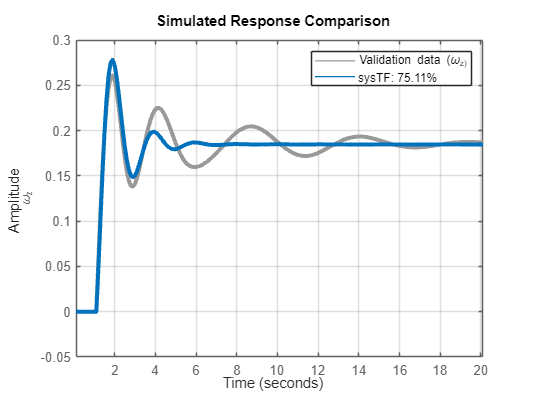

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

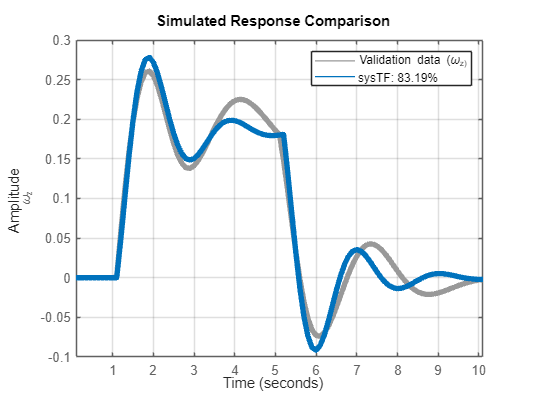

compare(validation_data, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

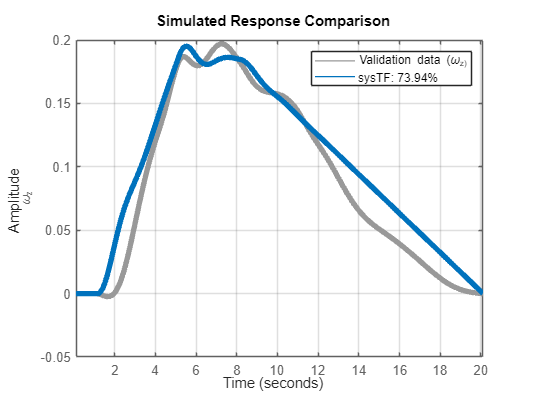

compare(validation_data2, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

**Identify a state space model**

Gss = ssest(data, 1:10) % estimate state space model of order 1:10

Gss =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4
   x1   -0.1126    -1.334   -0.1987    0.0202
   x2     1.026   -0.1055     0.198    -0.282
   x3    0.2696     -0.98    -0.441     3.129
   x4  -0.05163     2.172    -2.301    -2.724
 
  B = 
       \delta_a
   x1     3.859
   x2    -6.875
   x3     92.22
   x4    -89.43
 
  C = 
                   x1        x2        x3        x4
   \omega_z     0.111  -0.04135  -0.01288  -0.01123
 
  D = 
             \delta_a
   \omega_z         0
 
  K = 
       \omega_z
   x1     42.94
   x2    -110.8
   x3    -313.1
   x4     510.5
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 28
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        

Gest = tf(Gss) % turn stat-space back into TF

Gest =
 
  From input "\delta_a" to output "\omega_z":
    0.5286 s^3 + 2.379 s^2 + 0.8283 s + 2.236
  ---------------------------------------------
  s^4 + 3.383 s^3 + 11.33 s^2 + 6.358 s + 12.81
 
Continuous-time transfer function.
Model Properties


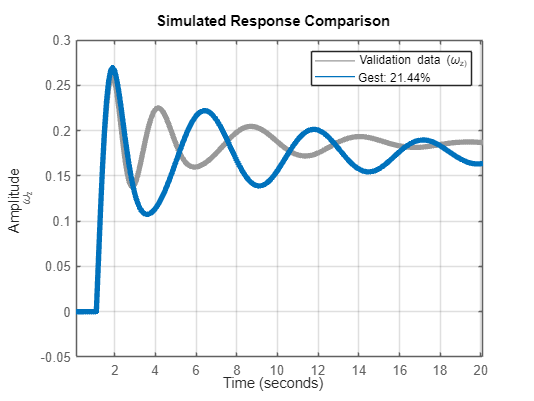

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data, Gest, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 4);
grid on